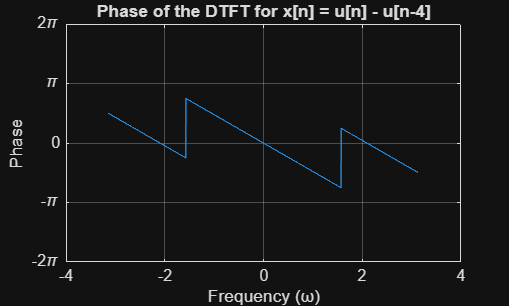

% Queswtion 2.4B]

% Define the frequency vector from -pi to pi
w = -pi:pi/1000:pi;

% 1. Calculate the DTFT X(e^jw) for the pulse x[n] = u[n] - u[n-4]
% Length L=4, centered at n=1.5
numerator = (1 - exp(-1j * 4 * w));
denominator = (1 - exp(-1j * w));
X_ejw = numerator ./ (denominator + eps); % Add epsilon to avoid division by zero at w=0

% 2. Calculate the Phase
phase_X = angle(X_ejw);

% 3. Plot the Phase
figure;
plot(w, phase_X);
title('Phase of the DTFT for x[n] = u[n] - u[n-4]');
xlabel('Frequency (ω)');
ylabel('Phase');
yticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi]); % Label y-axis ticks with multiples of pi
yticklabels({'-3\pi', '-2\pi', '-\pi', '0', '\pi', '2\pi', '3\pi'});
ylim([-2*pi 2*pi]);
grid on;

% 2.4 C
% Define the frequency vector over the fundamental period [-pi, pi]
w = -pi:pi/500:pi;

% --- 1. Calculate the Magnitude |R(e^jω)| ---
% The formula for the DTFT is R(e^jw) = (sin(3w) / sin(w/2)) * exp(-j*5*w).
% The magnitude is the square of the magnitude of the Dirichlet sinc function.
% We add a small constant (eps) to the denominator to prevent division by zero at w=0.
magnitude_R = (sin(3*w) ./ (sin(w/2) + eps)).^2

magnitude_R =     0.0000    0.0004    0.0014    0.0032    0.0057    0.0089    0.0127    0.0173    0.0226    0.0285    0.0351    0.0424    0.0504    0.0590    0.0682    0.0780    0.0885    0.0995    0.1111    0.1233    0.1361    0.1493    0.1631    0.1774    0.1922    0.2074    0.2230    0.2391    0.2556    0.2725    0.2897    0.3072    0.3251    0.3432    0.3616    0.3802    0.3991    0.4181    0.4373    0.4566    0.4761    0.4956    0.5152    0.5348    0.5545    0.5741    0.5936    0.6131    0.6325    0.6518


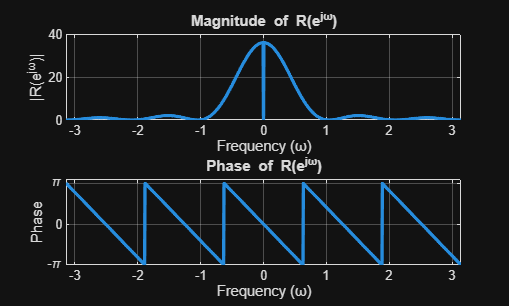


% --- 2. Calculate the Phase ∠R(e^jω) ---
% The phase is purely linear, phi(w) = -5w.
% MATLAB's 'angle' function handles the 2*pi wrapping automatically.
phase_R = -5*w;

% To make the plot look like the principal value plot (between -pi and pi),
% we can use the 'unwrap' function on the phase, but the linear unwrapped
% phase is often preferred for conceptual understanding. We will plot the
% wrapped phase to show the saw-tooth pattern.
wrapped_phase = angle(exp(1j * phase_R)); % Wrap the phase to the (-pi, pi] range

% --- Plotting ---
figure;

% Subplot 1: Magnitude
subplot(2,1,1);
plot(w, magnitude_R, 'LineWidth', 2);
title('Magnitude of R(e^{jω})');
xlabel('Frequency (ω)');
ylabel('|R(e^{jω})|');
xlim([-pi pi]);
grid on;

% Subplot 2: Phase
subplot(2,1,2);
plot(w, wrapped_phase, 'LineWidth', 2);
title('Phase of R(e^{jω})');
xlabel('Frequency (ω)');
ylabel('Phase');
yticks([-pi 0 pi]);
yticklabels({'-\pi', '0', '\pi'});
xlim([-pi pi]);
ylim([-pi 1.1*pi]); % Adjust y-limits slightly for clarity
grid on;